# Example implementation for computing the basin of attraction

## Using nested loops is slow

The tolerance doesn't have to be terribly tight, because near a root Newton's method converges rapidly.

For some reason this is twice as fast if it is run from a plain m-file.

tol = 1e-1;
p = [1 0 0 -1];
np = length(p) - 1;
dp = polyder(p);
r = roots(p);
M = 1000;
x = linspace(-1.2, 1.2, 100);
y = linspace(-1.2, 1.2, 100);
C = zeros(length(y), length(x)); % Root numbers are used as color indices
cmap = [1 0 0; 0 1 0; 0 0 1; 0 0 0]; % Color map for np = 3
tic
for m = 1:length(x)
    for n = 1:length(y)
        done = false;
        z = x(m) + 1i*y(n);
        % Loop until the iteration converges to a root
        % or diverges to infinity
        while ~done
            z = z - polyval(p, z)/(polyval(dp, z) + eps);
            k = find(abs(z - r) < tol); % Check if near a root
            if ~isempty(k)
                C(n, m) = k;
                done = true;
            elseif abs(z) > M
                C(n, m) = np + 1; % Last color is black for divergence
                done = true;
            end
        end
    end
end
toc

Elapsed time is 0.340499 seconds.


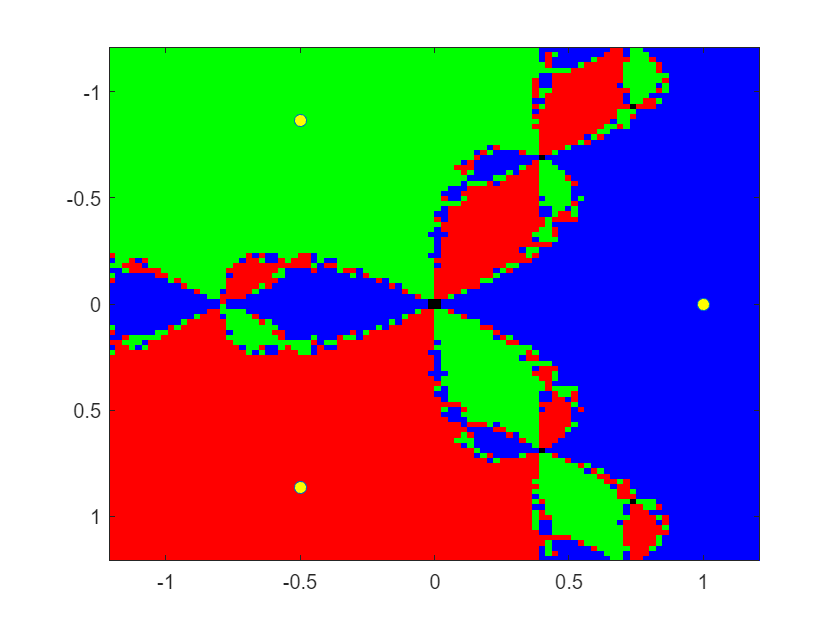

image(x, y, C);
colormap(cmap);
hold on
plot(r, 'o', 'MarkerFaceColor', 'y')
hold off

## Vectorizing is much faster

The first color of the color map is white for points which don't converge to any root or diverge to infinity within `maxiter` iterations. Try decreasing `maxiter` to see this. This couldn't happen in the slower version, because there we iterate until convergence to a root or divergence to infinity.

p = [1 0 0 -1];
np = length(p) - 1;
dp = polyder(p);
r = roots(p);
tol = 1e-1;
M = 1000;
x = linspace(-1.2, 1.2, 10);
y = linspace(-1.2, 1.2, 10);
C = zeros(length(y), length(x), 'uint8');
cmap = [1 1 1; 1 0 0; 0 1 0; 0 0 1; 0 0 0];
[X, Y] = meshgrid(x, y);
Z = X + 1i*Y;
maxiter = 100;
tic
for j = 1:maxiter
    Z = Z - polyval(p, Z)./(polyval(dp, Z) + eps); % To avoid division by zero
    for k = 1:np
        C(abs(Z - r(k)) < tol) = k;
    end
    C(abs(Z) > M) = np + 1;
end
toc

Elapsed time is 0.015014 seconds.


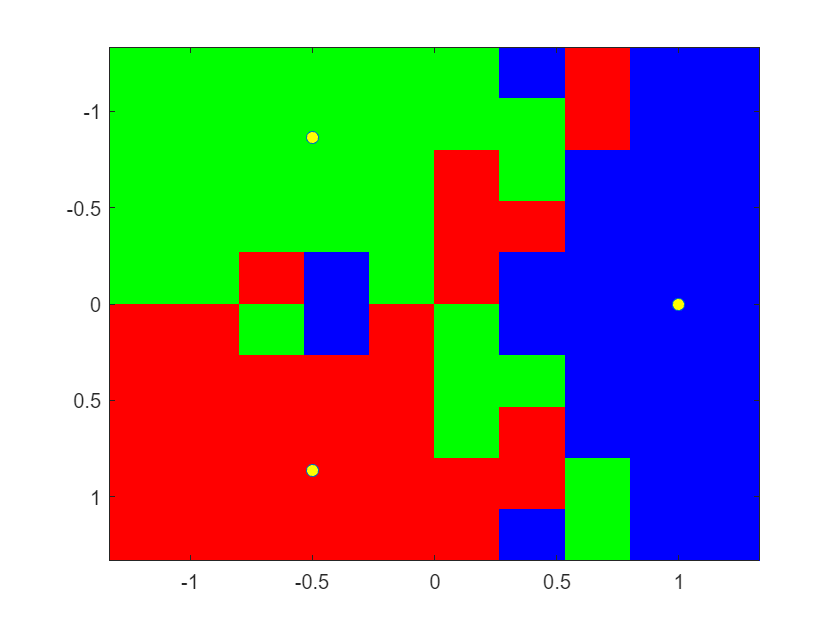

image(x, y, C);
colormap(cmap);
hold on
plot(r, 'o', 'MarkerFaceColor', 'y')
hold off